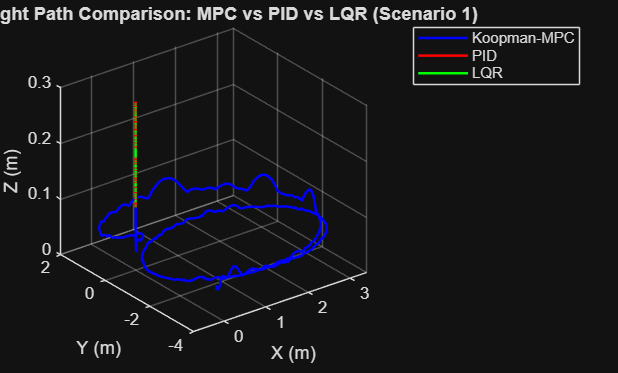

% Set project root explicitly (works reliably in Live Scripts too)
projectRoot = 'D:\Projects\koopman-mpc-drone';

mpc = load(fullfile(projectRoot, 'results', 'matlab_export', 'mpc_scenario_1.mat'));
pid = load(fullfile(projectRoot, 'results', 'matlab_export', 'pid_scenario_1.mat'));
lqr = load(fullfile(projectRoot, 'results', 'matlab_export', 'lqr_scenario_1.mat'));

figure;
plot3(mpc.x, mpc.y, mpc.z, 'b', 'LineWidth', 1.5); hold on;
plot3(pid.x, pid.y, pid.z, 'r', 'LineWidth', 1.5);
plot3(lqr.x, lqr.y, lqr.z, 'g', 'LineWidth', 1.5);
xlabel('X (m)'); ylabel('Y (m)'); zlabel('Z (m)');
title('3D Flight Path Comparison: MPC vs PID vs LQR (Scenario 1)');
legend('Koopman-MPC', 'PID', 'LQR');
grid on;

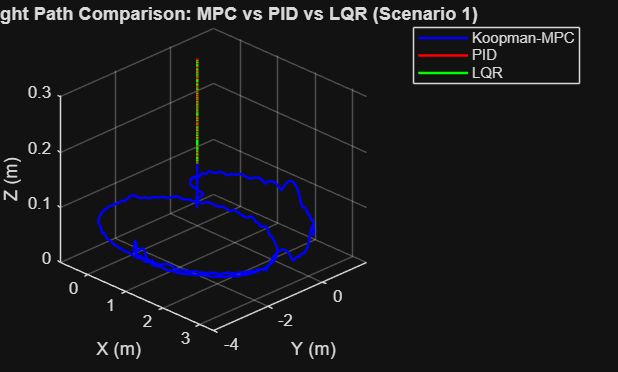

view(45, 30);